01.Cds센서의 시간에 따른 출력 전압(V1)을 analogRead함수를 통해 얻어진 데이터 (V2의 ADC 결과값)으로부터계산하고 이를 그래프로 나타내면서 분석하시오.

# 1. Data Loading

data = importdata('첨부파일1_cds초음파센서.txt')

data =    583    18
   582    18
   582    18
   582    18
   582    18
   582    18
   582    18
   582    18
   582    18
   582    18


# 2. V2 : analogRead 함수를 통해 10-bit resolution된 값만 V2만 추출

V2 = data(:,1)

V2 =    583
   582
   582
   582
   582
   582
   582
   582
   582
   582


# 3. V2 : analogRead값(0~1023, 10-bit resolution)을 0~5V 범위로 변환

V2 = V2 .* (5/1023)

V2 =     2.8495
    2.8446
    2.8446
    2.8446
    2.8446
    2.8446
    2.8446
    2.8446
    2.8446
    2.8446


# 4. V2, R2의 정보로 R1 구하기

% V2 = (R2/(R1+R2)) * 5
R2 = 10000

R2 = 10000

R1 = (5*R2)./V2 - R2

R1 = 1.0e+03 *

    7.5472
    7.5773
    7.5773
    7.5773
    7.5773
    7.5773
    7.5773
    7.5773
    7.5773
    7.5773


# 5. R1의 정보로 V1 구하기

% V1 = (R1/(R1+R2)) * 5
V1 = (R1./(R1+R2)) .* 5

V1 =     2.1505
    2.1554
    2.1554
    2.1554
    2.1554
    2.1554
    2.1554
    2.1554
    2.1554
    2.1554


# 6. Graph 시각화 : 시간 t에 따른 V1의 변화

## 6_1. Sensing한 시간 파악하기

t_len = length(V1) % 0.5초 동안 t_len개 sampling한 것

t_len = 605

total_sec = t_len * 0.5 % 605 * 0.5초 = 302.5초 = 약 5분 동안 Sensing

total_sec = 302.5000

minute = floor(total_sec / 60); % 분 계산
second = mod(total_sec, 60);    % 초 계산
fprintf('총 %d분 %d초 동안 sensing하였습니다.\n', minute, second);

총 5분 2.500000e+00초 동안 sensing하였습니다.


## 6_2. Graph 그릴 data 준비

% t는 0.5sec 간격으로 Sampling했기 때문에 전체 길이를 0.5 간격으로 나눈다.
x = (0 : 1 : t_len-1) * 0.5  % x축 데이터 생성

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


y = V1;                     % y축 데이터 생성


## 6_3. Graph 그리기

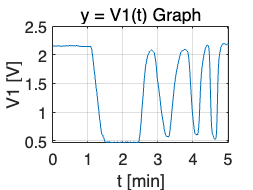

grid on
plot(x, y);
xlabel('t [min]');      % x축 label 설정 
ylabel('V1 [V]');       % y축 label 설정 (시간에 따른 출력 전압 V1)
xticks(0 : 60 : 60*(minute+1))   % x축 눈금 지정
xticklabels(0 : 1 : minute+1)    % x축 눈금 label 설정
title('y = V1(t) Graph');  
grid on;

# 7. Graph 분석

%{ 

출력된 Graph를 바탕으로 다음과 같이 분석할 수 있다.

옴의 법칙 : V=IR -> V와 R은 비례관계임으로 다음과 같은 분석을 할 수 있다.
    * 약 0 ~ 1분 : V1값이 유지되고 있다 == R1이 유지되고 있다 == 밝기가 유지되고 있다
    * 약 1분 ~ 1분 30초 : V1이 급격히 작아지고 있다 == R1이 작아지고 있다 == 밝기가 밝아지고 있다
    * 약 1분 30초 ~ 2분 30초 : V1값이 유지되고 있다 == R1이 유지되고 있다 == 밝기가 밝은 상태로 유지되고 있다
    * 약 2분 30초 ~ 2분 40초 : V1이 급격히 커지고 있다. == R1이 커지고 있다 == 밝기가 어두워지고 있다
    * 약 2분 40초 ~ 약 5분 : V1이 작아지고 커지고 반복 == R1이 작아지고 커지고 반복 == 밝기가 밝아졌다 어두워졌다 반복한다
    * sensing을 종료할 때는 sensing 시작할 때와 비슷한 밝기로 만들며 종료한다.
%}

